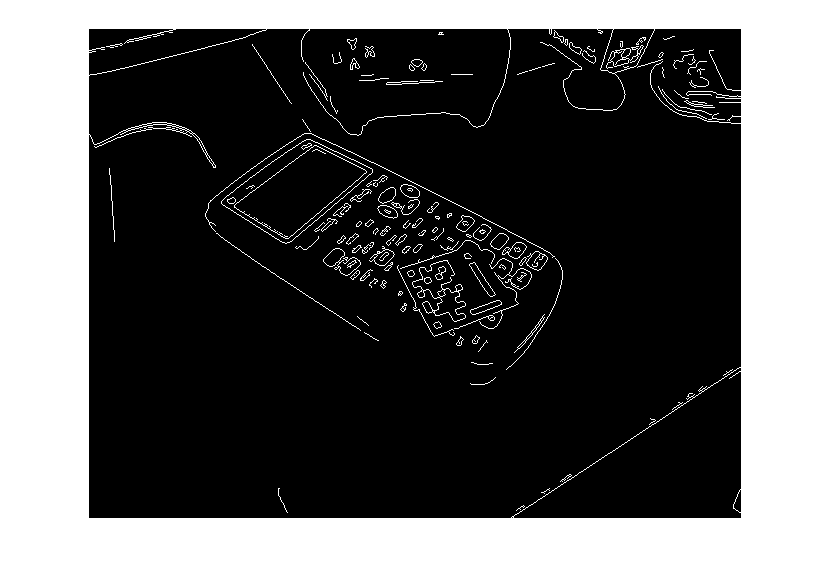

TestImage1 = imread('im2.jpg');
%TestImage1 = imread('im4.png');
%TestImage1 = imread("training_1.jpg");

TestImage1 = imsharpen(TestImage1);

TestImage1 = imresize(TestImage1, 0.5);
%TestImage1 = imrotate(TestImage1, -45);

TestG = rgb2gray(TestImage1);

%TestG = medfilt2(TestG, [10 10]);

%AveFilter = ones(5,5)*1/9;
%TestG = imfilter(TestG, AveFilter);

bw = edge(TestG);

%L = bwlabel(bw);

%Fine tune the bw

%MaxRegions = max(max(L));
MaxPixels = 10;



[L,num] = bwlabel(bw);

%L = imfill(L);

%L = bwareaopen(L, MaxPixels);

counts = sum(bsxfun(@eq,L(:),1:num));
B1 = bsxfun(@eq,L,permute(find(counts>MaxPixels),[1 3 2]));
L2 = sum(B1,3)>0;

imshow(L2);

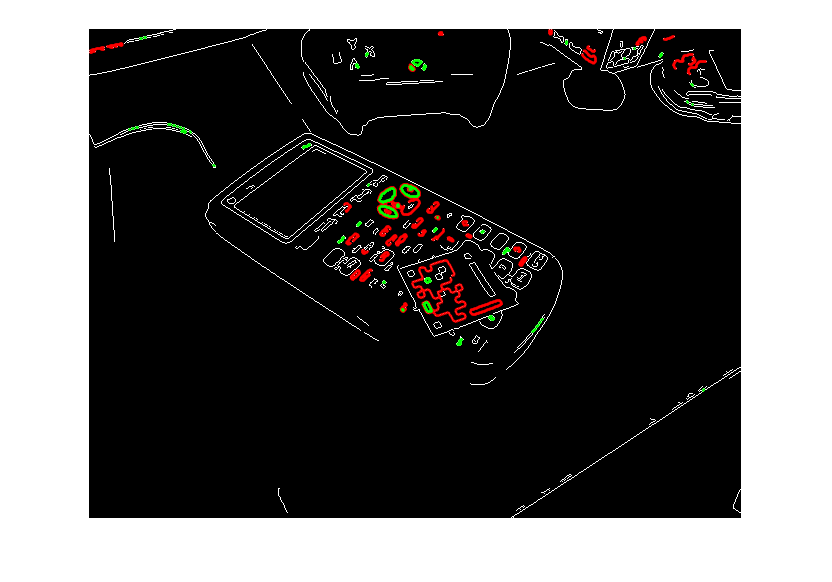


[B,L,N,A] = bwboundaries(L2);

Parameters = zeros(length(B), 5); %MinX, MinY, MaxX, MaxY
ParametersGuide = zeros(length(B), 5); %MinX, MinY, MaxX, MaxY


PotentialGuides = 0;
PotentialCornerstones = 0;

imshow(L2); hold on;

for k=1:length(B)
   boundary = B{k};
   
   [MinX,Ixmin] = (min(boundary(:, 1)));
   [MinY,Iymin] = (min(boundary(:, 2)));
   
   [MaxX,Ixmax] = (max(boundary(:, 1)));
   [MaxY,Iymax] = (max(boundary(:, 2)));
   
   Width = MaxX - MinX;
   Height = MaxY - MinY;
   
   CenterPos = [((MaxY-MinY)/2+MinY) ((MaxX-MinX)/2+MinX)];
   
   
   if CenterPos(1) >=180 && CenterPos(1) < 235
       testingAVC = 1;
   end
   
   Ratio = Width/Height;
   
   X = [MinX boundary(Iymin, 1) MaxX boundary(Iymax, 1)];
   Y = [boundary(Ixmin, 2) MinY boundary(Ixmax, 2) MaxY];
   
   RectParam = RectParameters(X, Y);
   
   RectParam = RectParam + 1;
   
   RatioGuide = RectParam(1,1)/RectParam(3,1);
   
   
   %Potential Cornerstones
   if Ratio >= 0.7 && Ratio <= 1.4
       PotentialCornerstones = PotentialCornerstones + 1;
       Parameters(PotentialCornerstones, :) = [Height Width CenterPos Ratio];
   end    
%        if(k > N)
%          plot(boundary(:,2), boundary(:,1), 'g','LineWidth',2);
%        else
%          plot(boundary(:,2), boundary(:,1), 'r','LineWidth',2);
%        end
   
   
    if RatioGuide >= 3 && RatioGuide <= 6
       PotentialGuides = PotentialGuides + 1;
       ParametersGuide(PotentialGuides, :) = [Height Width CenterPos Ratio];
       
       if(k > N)
         plot(boundary(:,2), boundary(:,1), 'g','LineWidth',2);
       else
         plot(boundary(:,2), boundary(:,1), 'r','LineWidth',2);
       end
    end
end

ApexCornerstones = 0;
Cornerstones = zeros(100, 3);

%ParametersSort = unique(Parameters(:, 3:4), 'rows');

%Parameters(1:length(ParametersSort), 3:4) = ParametersSort;

%Verify Cornerstones
for Apex = 1:PotentialCornerstones
        ApexPos = [Parameters(Apex, 3) Parameters(Apex, 4)];
        
        ApexWidth = Parameters(Apex, 2);
        
        for SideR = 1:PotentialCornerstones
            SideRPos = [Parameters(SideR, 3) Parameters(SideR, 4)];
            
            dApexSideR = norm(ApexPos - SideRPos);
            
            MaxDistance = 13*ApexWidth;
            MinDistance = 8*ApexWidth;
            
            if dApexSideR > MinDistance && dApexSideR < MaxDistance
                
    
                for SideL = 1:PotentialCornerstones
                    
                    SideLPos = [Parameters(SideL, 3) Parameters(SideL, 4)];
                    
                    dApexSideL = norm(ApexPos - SideLPos);
                    
                    dSide = norm(SideLPos - SideRPos);
                    
                    MaxSide = sqrt(MaxDistance^2 + MaxDistance^2);
                    MinSide = sqrt(MinDistance^2 + MinDistance^2);
                    
                    Angle = acos((dApexSideR^2 + dApexSideL^2 - dSide^2)/(2*dApexSideR*dApexSideL))*180/pi;
                    
                    if dApexSideL > MinDistance && dApexSideL < MaxDistance && Angle > 75 && Angle < 110
                        if dSide > MinSide && dSide < MaxSide
                            
                            %Find a matching short guide
                            for Guide = 1:PotentialGuides
                                GuidePos = [ParametersGuide(Guide, 3)  ParametersGuide(Guide, 4)];
                                
                                dApexGuide = norm(ApexPos - GuidePos);
                                
                                if dApexGuide > MinDistance && dApexGuide < MaxDistance
                                    ApexCornerstones = ApexCornerstones + 1;
                                    Cornerstones(ApexCornerstones, :) = [Apex SideR SideL];
                                end
                                
                            end
                            

                        end
                    end
                    
                end
            
            end
        end
end




% [C,ia,ic] = unique(Cornerstones(1:10,1:3), 'rows');
% [C,ia,ic] = unique(C(2:3,1:3), 'rows');

% for k = 1:length(Parameters)
% 
% end

% for Region = 1:MaxRegions
%     
%     Count = 0;
%     
%     for X = 1:size(L, 1)
%         for Y = 1:size(L,2)
%             
%             if L(X,Y) == Region
%                 Count = Count + 1;
%             end
%         end
%     end
%     
%     for X = 1:size(L, 1)
%         for Y = 1:size(L,2)
%             
%             if Count < MaxPixels
%                 L(X,Y) = 0; %Delete it
%             end
%         end
%     end
%     
% end

%imshow(bw);

% s = regionprops(bw,{...
%     'Centroid',...
%     'MajorAxisLength',...
%     'MinorAxisLength',...
%     'Orientation'});
% 
% PotGuides = zeros(length(s),1);
% PotCorner = zeros(length(s),1);
% 
% PotGuidesNum = 0;
% PotCornerNum = 0;
% TotalMarkers = 0;
% 
% CornerRatioMax = 1.4;
% MaxGuide = 9;
% MinGuide = 3;
% MaxDistance = 5.5;
% 
% %Find guidelines
% for Index = 1:length(s)
%     %Extract parameters from regionprops
%     a = s(Index).MajorAxisLength/2;
%     b = s(Index).MinorAxisLength/2;
%     Xc = s(Index).Centroid(1);
%     Yc = s(Index).Centroid(2);
%     angle = s(Index).Orientation;
%     
%     Ratio = a/b;
%     
%     %Possible Cornerstones
%     if Ratio > CornerRatioMax - .8 && Ratio < CornerRatioMax
%         PotCornerNum = PotCornerNum + 1;
%         PotCorner(PotCornerNum) = Index;
%     else
%     %Possible Guidelines
%         if Ratio >= MinGuide && Ratio <= MaxGuide
%             PotGuidesNum = PotGuidesNum + 1;
%             PotGuides(PotGuidesNum) = Index;
%         end
%     end
% end
% 
% imshow(TestG);
% 
% %Iterate through every potential guideline
% for Guide = 1:PotGuidesNum
%     GuideA = s(PotGuides(Guide));
%     
%     a = GuideA.MajorAxisLength/2;
%     
%     Width = GuideA.MinorAxisLength;
%     
%     Xc = GuideA.Centroid(1);
%     Yc = GuideA.Centroid(2);
%     angle = GuideA.Orientation;
%     
%     Xc2 = a*cosd(angle) + Xc;
%     Yc2 = a*sind(angle) + Yc;
%     
%     LineA = ([Xc Yc Xc2 Yc2]);
%   
% %     
% %     CenterA = [Xc Yc];
% %     TipA = [Xc2 Yc2];
%     
%     Ratio = a/(Width/2);
%     
%     if Ratio >= 3 && Ratio <= 6
%         for Guide2 = 1:PotGuidesNum
%             GuideB = s(PotGuides(Guide2));
%             
%             %b = GuideB.MajorAxisLength/2;
%             %b = s(Index).MinorAxisLength/2;
%             XcB = GuideB.Centroid(1);
%             YcB = GuideB.Centroid(2);
%             angleB = GuideB.Orientation;
%             
%             Xc2B = b*cosd(angleB) + XcB;
%             Yc2B = b*sind(angleB) + YcB;
%             
%             LineB = [XcB YcB Xc2B Yc2B];
%             
%             %Distance = norm([Xc Yc] - [XcB YcB]);
%             IntPoint = intersect(LineA, LineB);
%             
%             if ~isempty(IntPoint)
%                 Distance = norm([Xc Yc] - IntPoint);
%                 
%                 DAngle = abs(angle - angleB);
%                 
%                 if DAngle >= 70 && DAngle <= 120 && ...
%                         Distance <= Width %&& Distance > (Width*(MaxDistance-4))
%                     
%                     TotalMarkers = TotalMarkers + 1;
%                     
%                 end
%             end
%             
%         end
%     end
% end




%bwC = imcontour(bw);

% s = regionprops(bw,{...
%     'Centroid',...
%     'MajorAxisLength',...
%     'MinorAxisLength',...
%     'Orientation'});
% 
% imshow(L2,'InitialMagnification','fit')
% 
% t = linspace(0,2*pi,50);
% 
% hold on
% for k = 1:length(s)
%     a = s(k).MajorAxisLength/2;
%     b = s(k).MinorAxisLength/2;
%     Xc = s(k).Centroid(1);
%     Yc = s(k).Centroid(2);
%     phi = deg2rad(-s(k).Orientation);
%     x = Xc + a*cos(t)*cos(phi) - b*sin(t)*sin(phi);
%     y = Yc + a*cos(t)*sin(phi) + b*sin(t)*cos(phi);
%     plot(x,y,'r','Linewidth',5)
% end
% hold off